%This scrip generates bar and violin graphs of the normalized responses

clear all

load 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1\NormalizedIndexesTable.mat';  %The matrix obtained from the fuction ExtractMatFiles.m


y_DEV_R = [ NormalizedIndexesTable(:,10).NormDEVca1 ; NormalizedIndexesTable(:,13).NormDEVcd2 ]; % Normalized deviant spikes

y_STD_R = [ NormalizedIndexesTable(:,11).NormSTDca1 ; NormalizedIndexesTable(:,14).NormSTDcd2 ]; % Normalized standard spikes

y_CTR_R = [ NormalizedIndexesTable(:,12).NormCTRca1 ; NormalizedIndexesTable(:,15).NormCTRcd2 ]; % Normalized control spikes

y_R = [y_DEV_R, y_CTR_R, y_STD_R]; %arrange in a matrix 

cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Spike Distributions\CA1';

save ('y_R.mat','y_R'); %Save said matrix

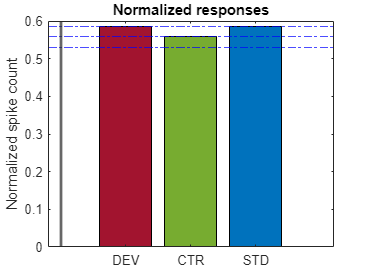

figure
y_s =[sum(y_R(:,1)); sum(y_R(:,2)); sum(y_R(:,3))];
y_m = [mean(y_R(:,1)); mean(y_R(:,2)); mean(y_R(:,1))];

%Bar graph
names = {"DEV"; "CTR"; "STD"};
b = bar(y_m);
set(gca,'xticklabel',names);
b.FaceColor = 'flat';
b.CData(1,:) = [0.6350 0.0780 0.1840];
b.CData(2,:) = [0.4660 0.6740 0.1880];
b.CData(3,:) = [0 0.4470 0.7410];
hold on

%It creates a line to show the top of the bar
yline(mean(y_R(:,1)),'-.b');
yline(mean(y_R(:,2)),'-.b');
yline(mean(y_R(:,3)),'-.b');

xline(0,'LineWidth',2);
title('Normalized responses');
ylabel('Normalized spike count');

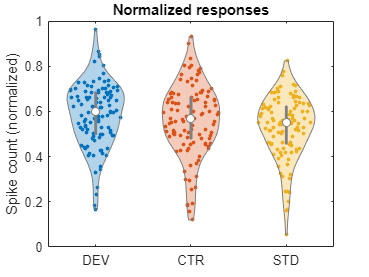

Assigning to 3 elements using a simple assignment statement is not supported. Consider using
comma-separated list assignment.

Related documentation


%Violin graphs
figure
varsNorm = {"NDEV", "NCTR", "NSTD"};
data = [y_R(:,1) y_R(:,2) y_R(:,3)];
vCats = ["DEV", "CTR", "STD"];
violinplot(data, vCats,  'ViolinAlpha', 0.3, 'MarkerSize', 8,'ShowWhiskers', false);
set(gca,'TickLabelInterpreter','none');
ylabel('Spike count (normalized)');
title("Normalized responses");

hold off